clear;

# BHZ 2D CUT_ORB

## useful tool

s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A0 A1 A2 B real;
syms k_x k_y k_z real;

### Model

M       = -M0+M2*(k_x^2+k_y^2)+M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
A       = A0+A2*(k_x^2+k_y^2)+A1*(k_z^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,3);
% 4: orbital number  dimension of mat
% 3: To k^3
%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*k_z*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*k_z*(k_x*k_y),sigma_y*tau_x )...
    ;

Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


C0     = 0;
A1     =  0    ;
A2     =  0    ;
BHZ = BHZ.Subsall('sym');

### PARA

% unit eV 
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A0      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C1     =  0     ;
C2     =  0     ;
M1     =  -0.5      ;
M2     =  -0.5  ;
B     =  1   ;
% unit    Ang
a      =  1        ;
b      =  1       ;
c      =  1        ;
BHZ = BHZ <'POSCAR_6';
BHZ_TB= BHZ.kp2TB();

### BULK

% bandplot
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_n = BHZ_TB_n <'KPOINTS_6';
EIGENCAR = BHZ_TB_n.EIGENCAR_gen();

BAND caculating 364/364 ...


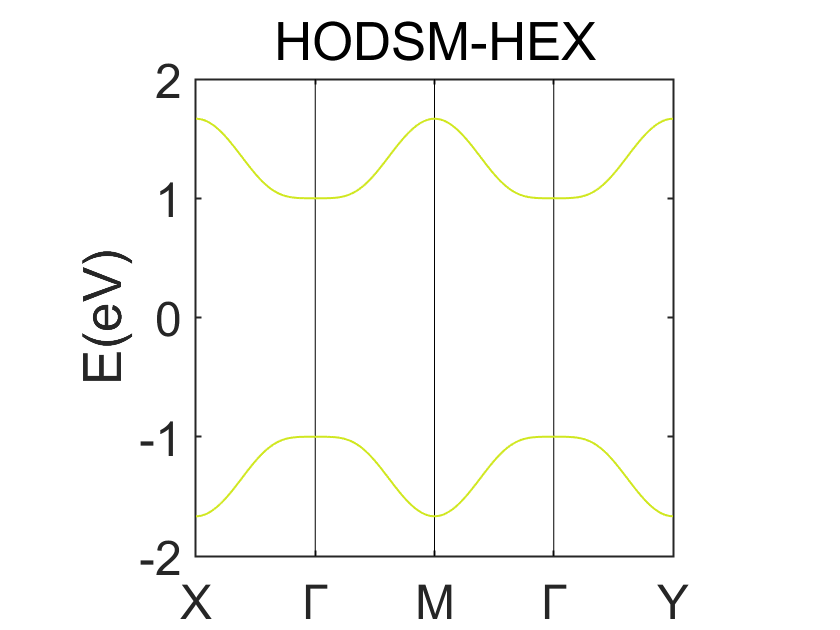

bandplot(EIGENCAR,[-2,2],'title',"HODSM-HEX",'KPOINTS','KPOINTS');   

## Nanodisk

Nslab = [20 20 1];
BHZ_TB_wire_n = BHZ_TB_n.Hnanowire_gen(Nslab);

Gen (1/3) NRPT z 
1 th NRPT z ---- Gen (1/3) NRPT y 
Gen NRPT x: 2/2
1 th NRPT z ---- Gen (2/3) NRPT y 
Gen NRPT x: 3/3
1 th NRPT z ---- Gen (3/3) NRPT y 
Gen NRPT x: 2/2
Gen (2/3) NRPT z 
2 th NRPT z ---- Gen (1/3) NRPT y 
Gen NRPT x: 2/2
2 th NRPT z ---- Gen (2/3) NRPT y 
Gen NRPT x: 3/3
2 th NRPT z ---- Gen (3/3) NRPT y 
Gen NRPT x: 2/2
Gen (3/3) NRPT z 
3 th NRPT z ---- Gen (1/3) NRPT y 
Gen NRPT x: 2/2
3 th NRPT z ---- Gen (2/3) NRPT y 
Gen NRPT x: 3/3
3 th NRPT z ---- Gen (3/3) NRPT y 
Gen NRPT x: 2/2


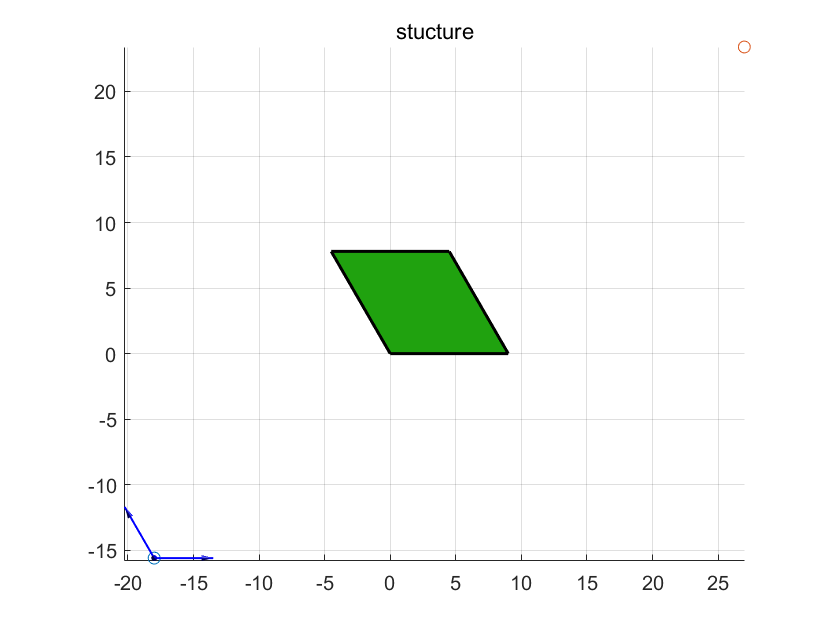

BHZ_TB_wire_n.show('NRPTS','vectorList',[0,0,0],'scale',3);
view(0,90);

### Hexagonal

#### cut

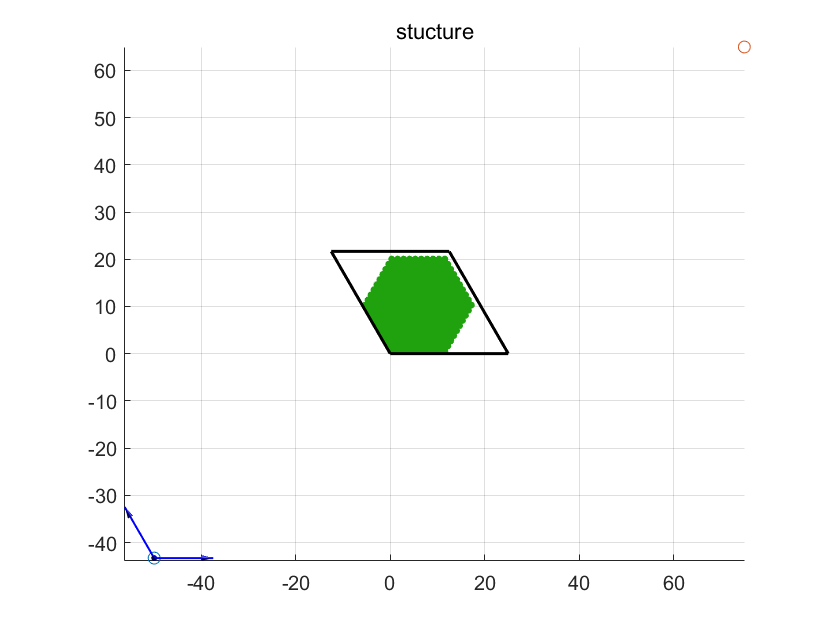

Nsuper = 20;
efsmall = 1e-6;
rmfunc = @(i1,i2,i3) ...
       i1 > 1-1/Nsuper   +efsmall |...
       i2 > 1-1/Nsuper   +efsmall |...
    i2-i1 > 0.5-1/Nsuper +efsmall | ...
    i2-i1 < -0.5+1/Nsuper-efsmall;
BHZ_TB_wire_cut_n = BHZ_TB_wire_n.cut_orb('rmfunc',rmfunc);
BHZ_TB_wire_cut_n.show('NRPTS','vectorList',[0,0,0],'scale',5);
view(0,90);

#### Nanowire

test = 2

test =      2


if test  == 1
    vacuum_mode = 1;
    np = 1;
    norb_enforce = -1;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_wire_cut_n.EIGENCAR_gen_wire([0,0,0],fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
    pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);
end

#### disk

if test  == 1
    kpoint_f = [0,0,0.1];
    [EIGENCAR,orb_list,WAVECAR]  = BHZ_TB_wire_cut_n.EIGENCAR_gen_disk([0,0,0],fermi,norb_enforce,kpoint_f,vacuum_mode,np);
    WAVEFUNC = WAVECAR(:,541:542);
    figure();
    plot(EIGENCAR,'-o','filled');
    figure();
    PARCHG_gen(orb_list,WAVEFUNC);
end

### Trigonal

#### cut

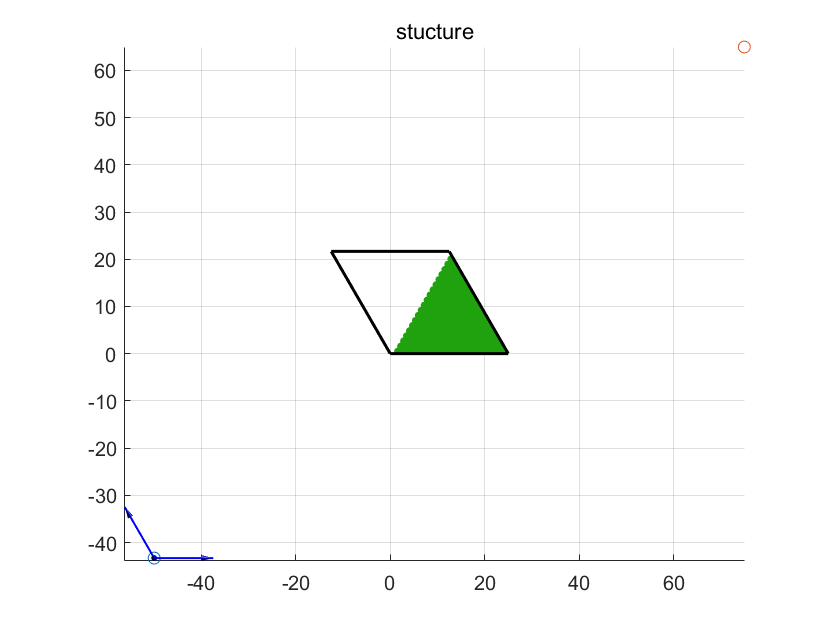

%BHZ_TB_wire_n = BHZ_TB_n.Hnanowire_gen([20,20,1]);
Nsuper = 30;
efsmall = 1e-6;
rmfunc = @(i1,i2,i3) i2-i1 > 0.0-1/Nsuper +efsmall ;
BHZ_TB_wire_cut_n2 = BHZ_TB_wire_n.cut_orb('rmfunc',rmfunc);
BHZ_TB_wire_cut_n2.show('NRPTS','vectorList',[0,0,0],'scale',5);
view(0,90);

#### nanowire

test = 2
if test  == 1
    vacuum_mode = 1;
    np = 1;
    norb_enforce = -1;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_wire_cut_n2.EIGENCAR_gen_wire([0,0,0],fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
    pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);
end

#### nanodisk

if test  == 1
    kpoint_f = [0,0,0.1];
    [EIGENCAR,orb_list,WAVECAR]  = BHZ_TB_wire_cut_n2.EIGENCAR_gen_disk([0,0,0],fermi,norb_enforce,kpoint_f,vacuum_mode,np);
    WAVEFUNC = WAVECAR(:,870:872);
    figure();
    plot(EIGENCAR,'-o');
    figure();
    PARCHG_gen(orb_list,WAVEFUNC);
end

### Rectangle

#### cut

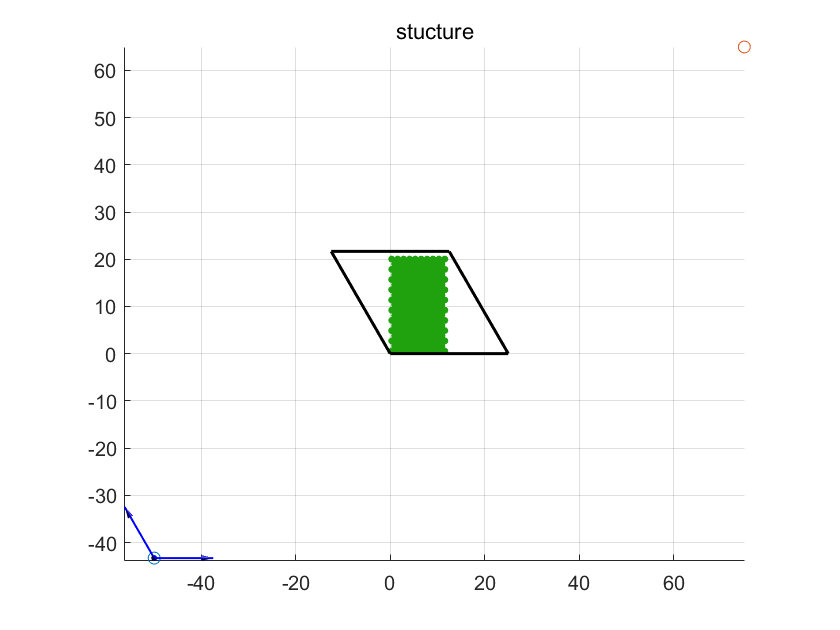

rmfunc = @(i1,i2,i3) ...
    i2 > 1-1/Nsuper   +efsmall |...
    i2-2*i1 > 0 +efsmall | ...
    i2-2*i1 < -1+1/Nsuper-efsmall;
BHZ_TB_wire_cut_n3 = BHZ_TB_wire_n.cut_orb('rmfunc',rmfunc);
BHZ_TB_wire_cut_n3.show('NRPTS','vectorList',[0,0,0],'scale',5);
view(0,90);

#### nanowire

test = 2
if test  == 1
    vacuum_mode = 1;
    np = 1;
    norb_enforce = -1;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_wire_cut_n3.EIGENCAR_gen_wire([0,0,0],fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
    pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);
end

#### nanodisk

if test  == 1
    kpoint_f = [0,0,0.1];
    [EIGENCAR,orb_list,WAVECAR]  = BHZ_TB_wire_cut_n3.EIGENCAR_gen_disk([0,0,0],fermi,norb_enforce,kpoint_f,vacuum_mode,np);
    WAVEFUNC = WAVECAR(:,842:843);
    figure();
    plot(EIGENCAR,'-o');
    figure();
    PARCHG_gen(orb_list,WAVEFUNC);
end


## rhombus

#### cut

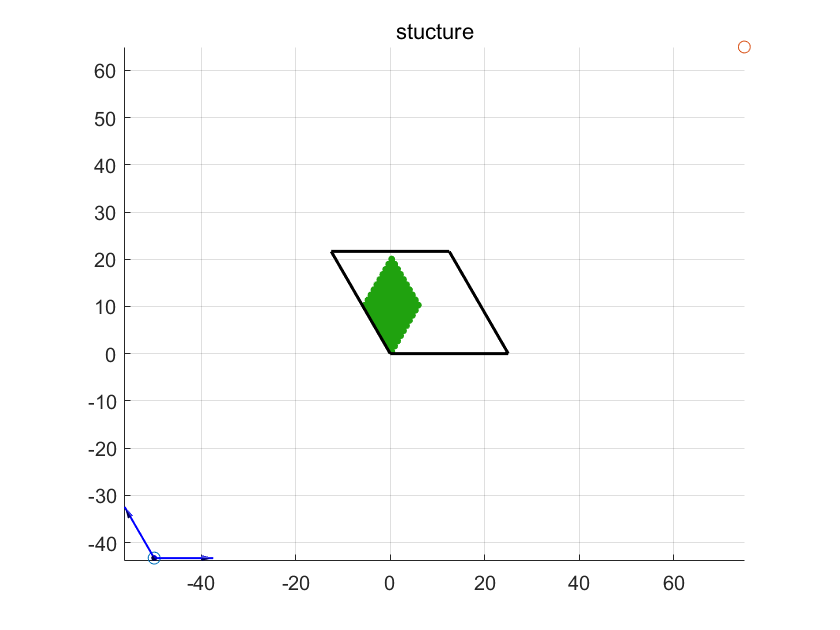

%BHZ_TB_wire_n = BHZ_TB_n.Hnanowire_gen([30,30,1]);
Nsuper = 20;
efsmall = 1e-6;
rmfunc = @(i1,i2,i3) ...
    i2-i1 < 0.0-1/Nsuper +efsmall |...
    i2-i1 > 0.5-1/Nsuper +efsmall |...
    i1 > 0.5 +efsmall ;
BHZ_TB_wire_cut_n4 = BHZ_TB_wire_n.cut_orb('rmfunc',rmfunc);
BHZ_TB_wire_cut_n4.show('NRPTS','vectorList',[0,0,0],'scale',5);
view(0,90);

#### nanowire

test = 2
if test  == 1
    vacuum_mode = 1;
    np = 1;
    norb_enforce = -1;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_wire_cut_n4.EIGENCAR_gen_wire([0,0,0],fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
    pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);
end

#### nanodisk

if test  == 1
    kpoint_f = [0,0,0.1];
    [EIGENCAR,orb_list,WAVECAR]  = BHZ_TB_wire_cut_n4.EIGENCAR_gen_disk([0,0,0],fermi,norb_enforce,kpoint_f,vacuum_mode,np);
    WAVEFUNC = WAVECAR(:,449:450);
    figure();
    plot(EIGENCAR,'-o');
    figure();
    PARCHG_gen(orb_list,WAVEFUNC);
end
